# 1 Task 2

%Initialize
image_dir = "images/Underwater";
images_all = Read_Images(image_dir, '*.jpg');

Reading images at - images\Underwater\*.jpg
Number of images found in directory: 3
Read 3/3


for i = 1:length(images_all)
    % resize the image so it runs faster
    resized_img = imresize(images_all{i}, 0.5);
end

## 2

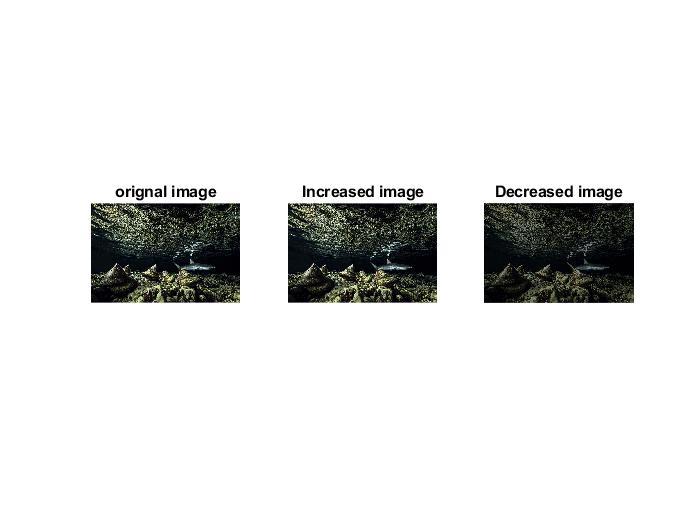

% image constrast
image =imread ('images/Underwater/underwater1.jpg');
%if target number from 0 anward it increased constrast and vice versa for the decreasing
increasedContrastImg=image*1;  
decreasedContrastImg= image*0.6;
f = figure(1);
subplot(1,3,1),imshow(image), title('orignal image');
subplot(1,3,2),imshow(increasedContrastImg), title('Increased image');
subplot(1,3,3),imshow(decreasedContrastImg), title('Decreased image'); 

## 3

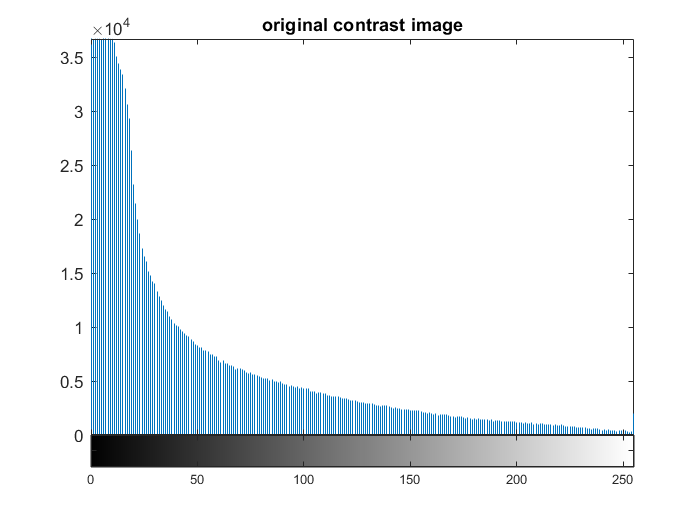

% contrast adjustment altrnative technique

%adding density to the original image
a=1;
imageAlternative = imadjust(image, [0.1 0.9]);
% for the increased contrast i believe this would be a less good candidate than
% the one above

%% showing in the histogaram
figure(2)
imhist(image), title('original contrast image')

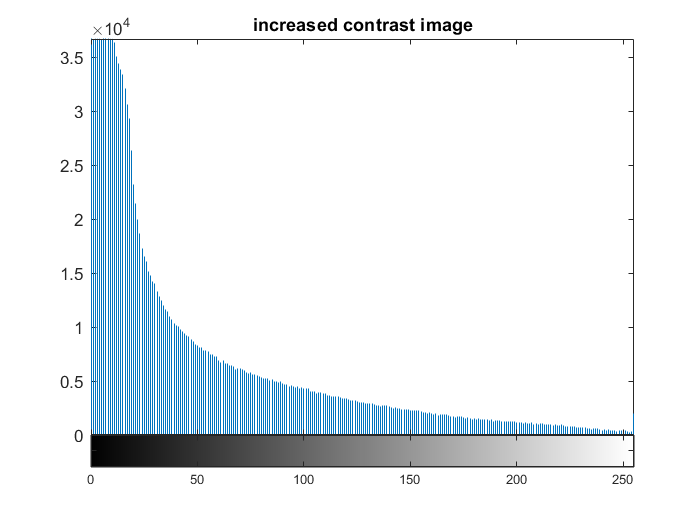

imhist(increasedContrastImg), title('increased contrast image')

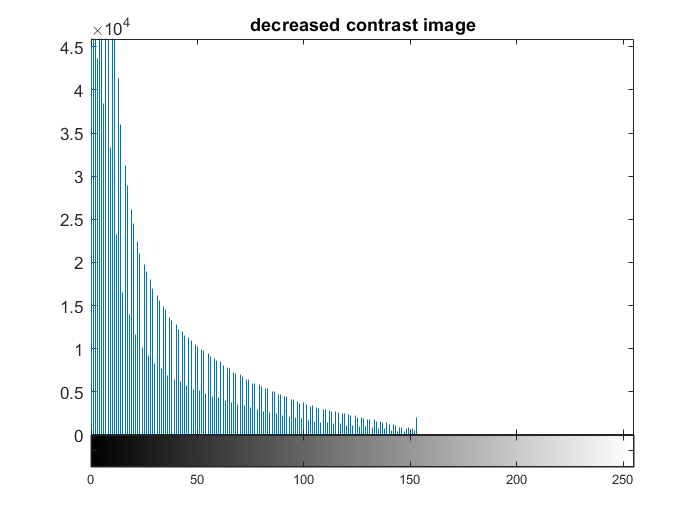

imhist(decreasedContrastImg),title('decreased contrast image')

## 2nd block

##  1. 2nd image Reading

image =imread('images/Underwater/underwater2.jpg');

## 2. Showing original image

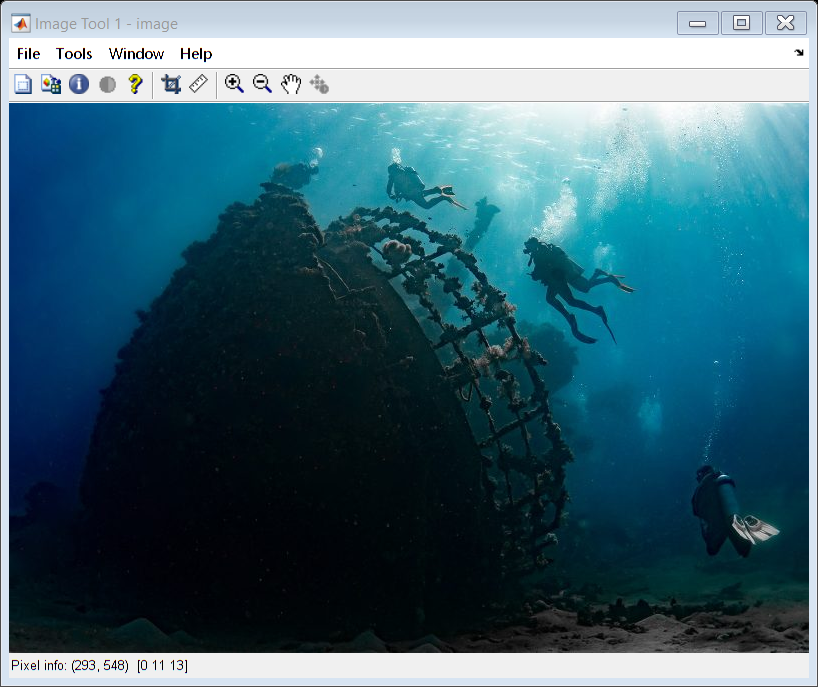

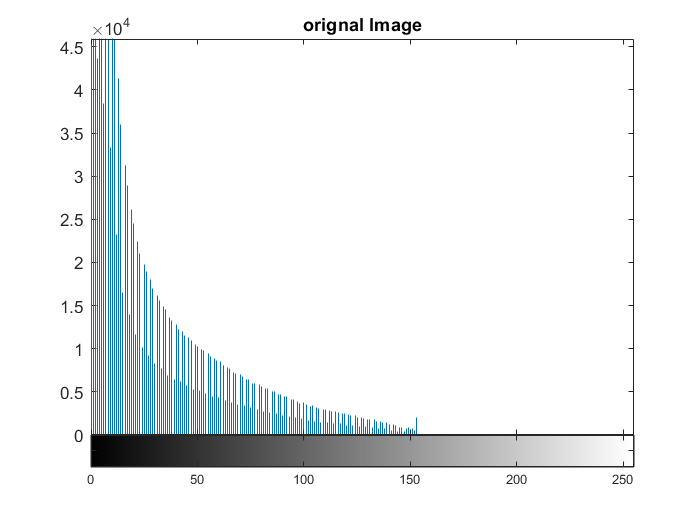

imtool(image), title('orignal Image');

## 3. Implication of contrast process

%if target number from 0 anward it increased constrast and Vice versa for the decreasing
increasedContrastImg = image*1.5;
decreasedContrastImg = image*0.6;

## 4. Show Enhanced contrast

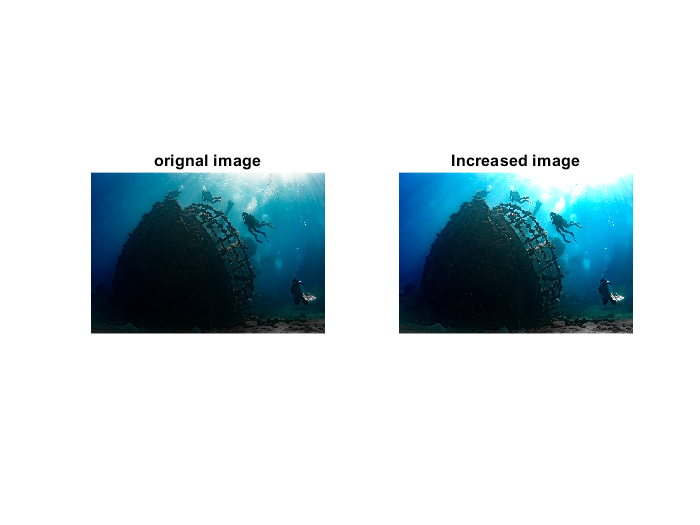

figure;
subplot(1,2,1),imshow(image), title('orignal image');
subplot(1,2,2),imshow(increasedContrastImg), title('Increased image');

## 5. Show Decreased contrast

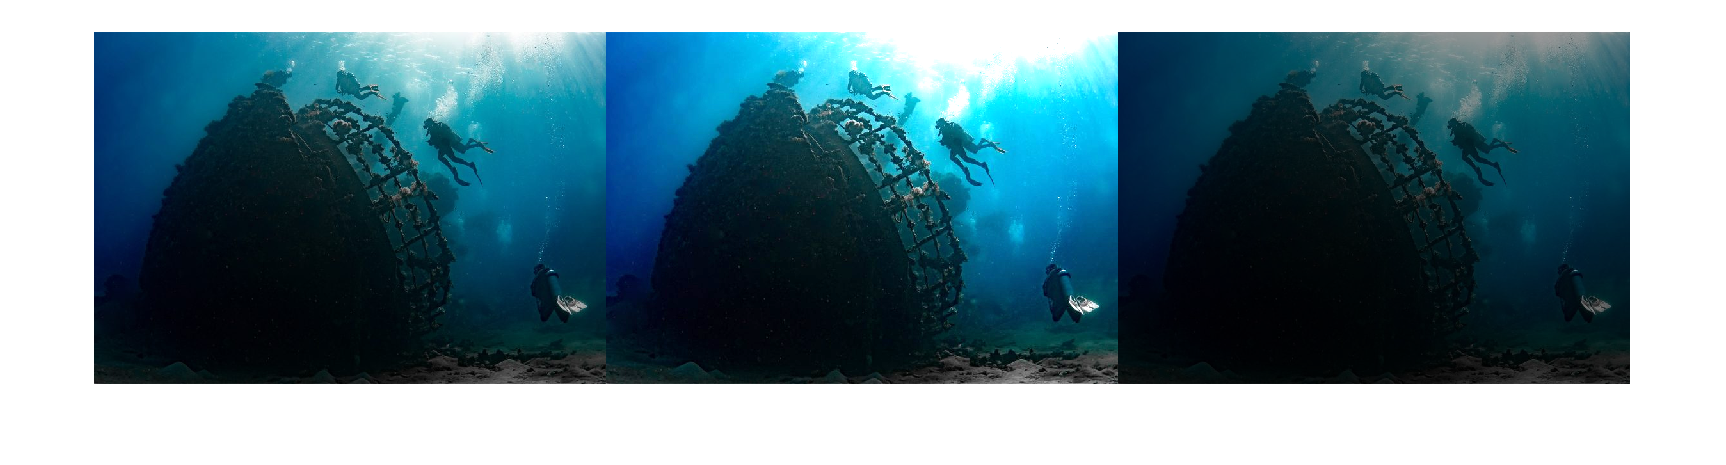

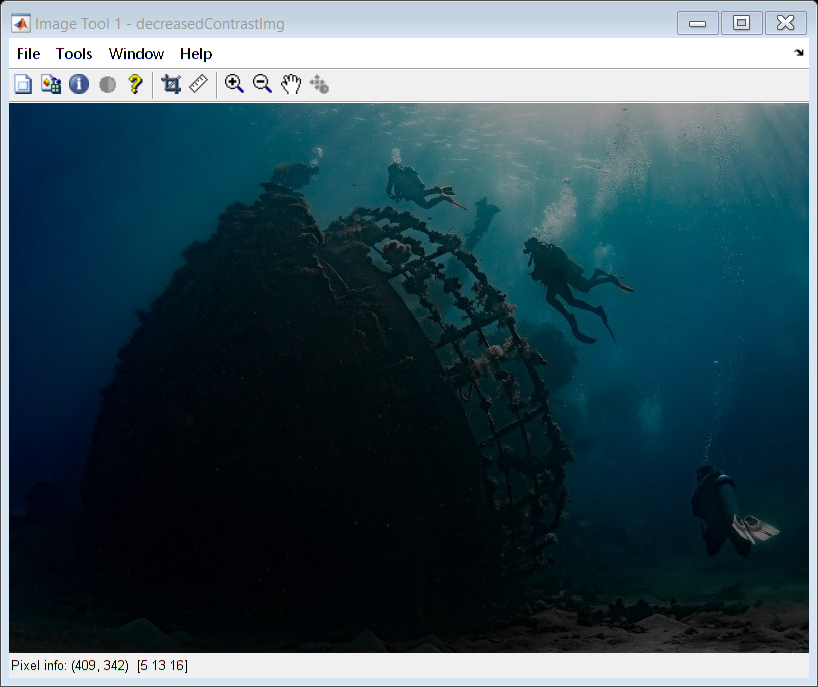

figure;
imtool(decreasedContrastImg);
montage({image, increasedContrastImg, decreasedContrastImg}, "Size",[1 3])

## 6. Apply alternate way for enhancing image

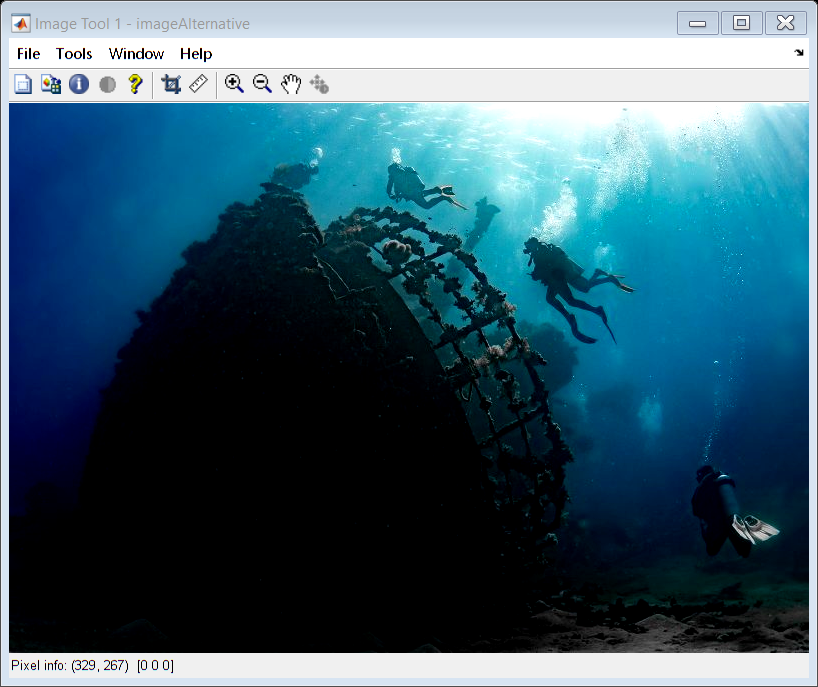

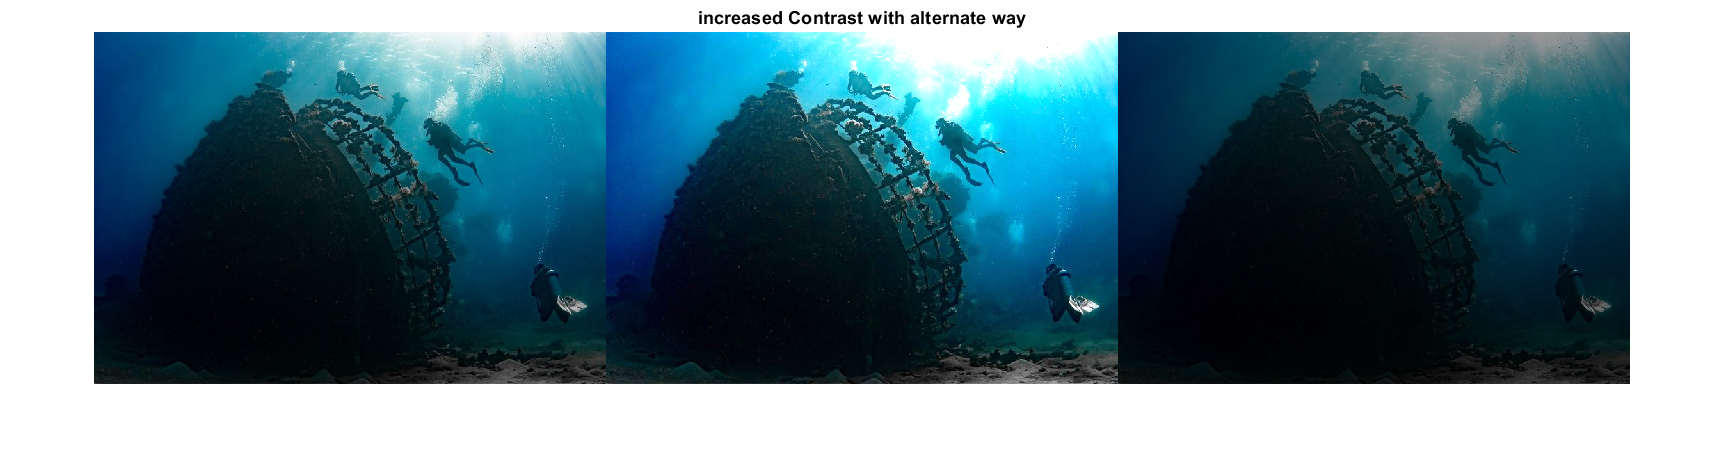

imageAlternative = imadjust(image, [0.1 0.9]);
imtool(imageAlternative), title('increased Contrast with alternate way');

## 3rd block

## 1. Reading and Showing Original Image

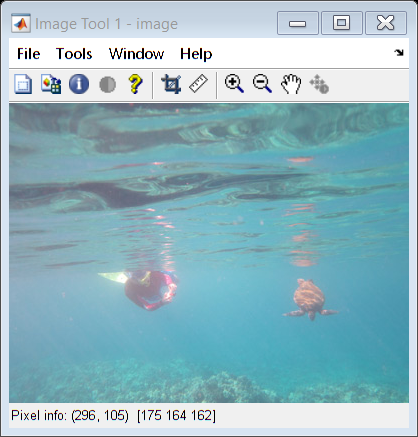

image =imread ('images/Underwater/underwater3.jpg');
imtool(image);

## 2. Enhancing image Contrast

%increasedContrastImg = image*1;
increasedContrastImg =histeq(image);
decreasedContrastImg = image*0.6;

## 3. Showing the Images after Inhancement

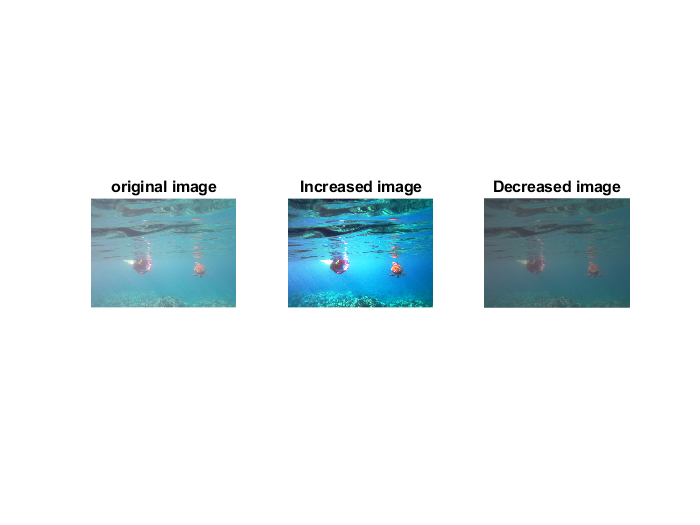

figure;
subplot(1,3,1), imshow(image), title('original image');
subplot(1,3,2), imshow(increasedContrastImg), title('Increased image');
subplot(1,3,3), imshow(decreasedContrastImg), title('Decreased image');

## Enhance color image and apply contrast [1]

Contrast enhancement of color images is typically done by converting the image to a color space that has image luminosity as one of its components, such as the L*a*b* color space. Contrast adjustment is performed on the luminosity layer L* only, and then the image is converted back to the RGB color space. Manipulating luminosity affects the intensity of the pixels, while preserving the original colors.

image = imread("images/Underwater/underwater3.jpg")
image_lab = rgb2lab(image);

%set the value of luminosity (the value ranges from 0 -100)
max_luminosity = 100;
L = image_lab(:,:,1)/ max_luminosity;
% Perform the three types of contrast adjustment on the luminosity channel, and keep the a* and b* channels unchanged. Convert the images back to the RGB color space.
image_lab(:,:,1) = imadjust(L)*max_luminosity;
image_lab = lab2rgb(image_lab)

% Display the original image and the three contrast adjusted images as a montage.
figure
montage({image,image_lab},"Size",[1 2])
title("Original Image and Enhanced Images using " + ...
    "image_lab,")

## Task#3. Linear Filters for images enhancement

% see week3Task3.mlx


## References

    [1]. [Contrast Enhancement Techniques](https://nl.mathworks.com/help/images/contrast-enhancement-techniques.html)